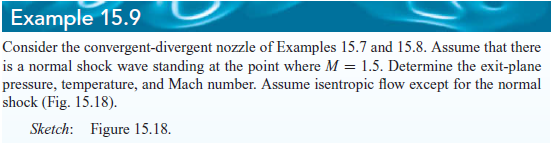

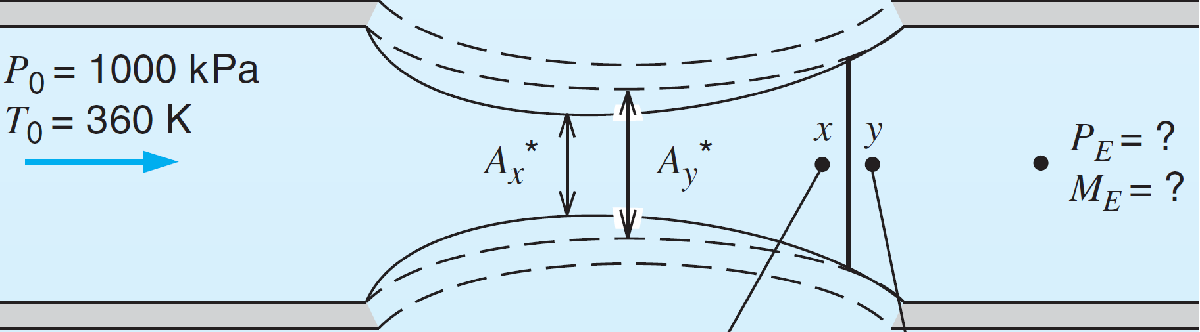

# given

u = symunit;
Ae = 1000*u.mm^2;
At = 500*u.mm^2;
pox = 1000*u.kPa;
Tox = 360*u.K;
Toy = 360*u.K;
Mx = 1.5;
air = ig;

# dowstream shock properties

My = air.My(Mx);
poy = pox*air.poy_pox(Mx);
Asx = At;
Asy = Asx*pox/poy;

# exit plane properties

syms Me;
f = matlabFunction(Ae/Asy-air.A_As(Me));
Me = fzero(f, [0.1 2]);
Me_vpa = vpa(Me, 3) %#ok

$$Me\_vpa = 0.332$$

pe = poy*air.p_po(Me);
pe_vpa = vpa(pe, 5) %#ok

$$pe\_vpa = 861.36\,\mathrm{kPa}$$

Te = Tox*air.T_To(Me);
Te_vpa = vpa(Te, 5) %#ok

$$Te\_vpa = 352.22\,K$$

clear Me_vpa pe_vpa Te_vpa;